# Carga de datos y generación de archivos

clc
clear all
datetime

ans = datetime
   07-Mar-2023 17:37:14



% https://totoro.banrep.gov.co/analytics/saw.dll?Download&Format=excel2007&Extension=.xlsx&BypassCache=true&path=%2Fshared%2fSeries%20Estad%C3%ADsticas_T%2F1.%20Tasa%20de%20Cambio%20Peso%20Colombiano%2F1.1%20TRM%20-%20Disponible%20desde%20el%2027%20de%20noviembre%20de%201991%2F1.1.1.TCM_Serie%20historica%20IQY&lang=es&SyncOperation=1
% archivo = 'HistoricoDolar.xlsx';
% historico = xlsread(archivo,-1);

database = xlsread ('DB Datos.xlsx');
dolar = xlsread ('DB Datos.xlsx',-1);
[num,txt,raw] = xlsread('HistoricoDolar.xlsx');
dolarhisto = readtable('HistoricoDolar.xlsx');


% Lee los datos del archivo

filename = 'DB Datos.xlsx';
sheet = 'Hoja1';
Meses = 'Mes';
[nume, txt, raw] = xlsread(filename, sheet);
[nums, txt, raw] = xlsread(filename, Meses);

% Extrae las fechas de la primera y última fila

primera_fecha = raw{2, 1};
ultima_fecha = raw{end, 1};

% Extrae los precios de la primera y última fila

primer_valor = raw{2, 2};
ultimo_valor = raw{end, 2};

% Muestra las fechas en la ventana de comandos

disp(['La primera fecha tomada fue: ', primera_fecha]);

La primera fecha tomada fue: 28/02/2023


fprintf('Y el precio del dolar era:  %.2f\n', primer_valor);

Y el precio del dolar era:  4802.75


disp(['La última fecha tomada fue: ', ultima_fecha]);

La última fecha tomada fue: 30/11/1991


fprintf('Y el precio del dolar era:  %.2f\n', ultimo_valor);

Y el precio del dolar era:  687.59



%----------------------------------------------------------------

## Análisis Estadístico

## (1) Calcular el promedio de los datos, y restar el valor obtenido al conjunto de datos.

Promedio.

promedio = mean(database);

%disp(promedio);

cambio_diario = diff(num)./num(1:end-1);
promedio_cambio = mean(cambio_diario);
fprintf('(1) El promedio del dólar es: %.2f\n', promedio);

(1) El promedio del dólar es: 2966.43


fprintf('(1) El cambio promedio del dólar es: %.8f\n', promedio_cambio);

(1) El cambio promedio del dólar es: 0.00024222


xlswrite('DB Datos.xlsx',{'Promedio';'cambio_diario';'promedio_cambio'},'Estadísticas','A2')
xlswrite('DB Datos.xlsx',[promedio;cambio_diario;promedio_cambio],'Estadísticas','B2')

## (2)Identificar el valor máximo y mínimo de la función

mx = max(database);
fprintf('(2) El valor maximo del dólar es: %.2f\n', mx);

(2) El valor maximo del dólar es: 5061.21


mn = min(database);
fprintf('(2) El valor minimo del dólar es: %.2f\n', mn);

(2) El valor minimo del dólar es: 1754.89


xlswrite('DB Datos.xlsx',{'valor maximo';'valor minimo'},'Estadísticas','A5')
xlswrite('DB Datos.xlsx',[mx;mn],'Estadísticas','B5')

%----------------------------------------------------------------

## (3) Calcular el rango,

Rango.

rango = range(database);
fprintf('(3) El valor rango del dólar es: %.2f\n', rango);

(3) El valor rango del dólar es: 3306.32


## La media (aritmética, geométrica y armónica).

media = mean(dolar);
media_aritmetica = mean(dolar);
media_geometrica = geomean(dolar);
media_armonica = harmmean(dolar);
fprintf('(3) La Media aritmética del dólar es: %.2f\n', media_aritmetica);

(3) La Media aritmética del dólar es: 2966.43


fprintf('(3) La Media geométrica del dólar es: %.2f\n', media_geometrica);

(3) La Media geométrica del dólar es: 2850.79


fprintf('(3) La Media armónica del dólar es: %.2f\n', media_armonica);

(3) La Media armónica del dólar es: 2732.84



% Mediana

mediana = median(dolar);
fprintf('(3) La Mediana del dólar es: %.2f\n', mediana);

(3) La Mediana del dólar es: 2994.62



% Moda

moda = mode(dolar);
fprintf('(3) La Moda del dólar es: %.2f\n', moda);

(3) La Moda del dólar es: 1797.68



% Desviación (estándar o típica

desviacion_estandar = std(dolar);
fprintf('(3) La desviación típica del dólar es: %.2f\n', desviacion_estandar);

(3) La desviación típica del dólar es: 811.94



% desviación media)

desviacion_media = mean(abs(dolar - media_aritmetica));
fprintf('(3) La desviación media del dólar es: %.2f\n', desviacion_media);

(3) La desviación media del dólar es: 647.64


% Esperanza,
esperanza = promedio;
fprintf('(3) La esperanza del dólar es: %.2f\n', esperanza);

(3) La esperanza del dólar es: 2966.43


% Varianza,
varianza = var(dolar);
fprintf('(3) La varianza del dólar es: %.2f\n', varianza);

(3) La varianza del dólar es: 659254.60


desviaciones = dolar - media;
varianza2 = sum(desviaciones .^ 2) / (length(dolar) - 1);
fprintf('(3) La varianza 2 del dólar es: %.2f\n', varianza2);

(3) La varianza 2 del dólar es: 659254.60


% Covarianza,
covarianza = cov(dolar);
fprintf('(3) La Covarianza del dólar es: %.2f\n', covarianza);

(3) La Covarianza del dólar es: 659254.60


% Coeficiente de variación (𝐶𝑉 =𝜎𝑥|𝑋̅|,𝑑𝑒𝑠𝑣𝑖𝑎𝑐𝑖ó𝑛 𝑒𝑠𝑡á𝑛𝑑𝑎𝑟 𝑦 𝑋̅ 𝑚𝑒𝑑𝑖𝑎 𝑎𝑟𝑖𝑡𝑚é𝑡𝑖𝑐𝑎),
coeficiente_variacion = desviacion_estandar / media;
fprintf('(3) La Coeficiente de variación del dólar es: %.4f\n', coeficiente_variacion);

(3) La Coeficiente de variación del dólar es: 0.2737


% coeficiente de variación de Pearson (𝑟 = 𝑆𝑥 |𝑥̅|, 𝑠𝑖𝑒𝑛𝑑𝑜 𝑆𝑥 𝑙𝑎 𝑑𝑒𝑠𝑣𝑖𝑎𝑐𝑖ó𝑛
% 𝑡í𝑝𝑖𝑐𝑎 𝑦 𝑥̅ 𝑙𝑎 𝑚𝑒𝑑𝑖𝑎 𝑑𝑒𝑙 𝑐𝑜𝑛𝑗𝑢𝑛𝑡𝑜 𝑑𝑒 𝑜𝑏𝑠𝑒𝑟𝑣𝑎𝑑𝑜𝑟𝑒𝑠),
coeficiente_pearson = (desviacion_estandar/media_aritmetica)*100;
fprintf('(3) La Coeficiente de variación de Pearson del dólar es: %.2f\n', coeficiente_pearson);

(3) La Coeficiente de variación de Pearson del dólar es: 27.37


% coeficiente de apertura (𝐶𝐴𝑃 = 𝑚á𝑥{𝑥𝑖} 𝑚í𝑛{𝑥𝑖}),

% coeficiente de asimetría (𝐴𝑆 = 𝑋̅− 𝑀0/𝑆, 𝑋̅ 𝑒𝑠 𝑙𝑎 𝑚𝑒𝑑𝑖𝑎 𝑎𝑟𝑖𝑡𝑚é𝑡𝑖𝑐𝑎,
% 𝑀0 𝑒𝑠 𝑙𝑎 𝑚𝑜𝑑𝑎 𝑦 𝑆 𝑒𝑠 𝑙𝑎 𝑑𝑒𝑠𝑣𝑖𝑎𝑐𝑖ó𝑛 𝑒𝑠𝑡á𝑛𝑑𝑎𝑟),
coef_asimetria = skewness(dolar);
%disp(coef_asimetria);
coefi_asimetria = ((media_aritmetica-moda)/desviacion_estandar);
fprintf('(3) El Coeficiente de asimetria arrojado es: %.2f\n', coef_asimetria);

(3) El Coeficiente de asimetria arrojado es: 0.13


fprintf('(3) El Coeficiente de asimetria calculado es: %.2f\n', coefi_asimetria);

(3) El Coeficiente de asimetria calculado es: 1.44


% kurtosis,
k = kurtosis(dolar);
fprintf('(3) La kurtosis es: %.2f\n', k);

(3) La kurtosis es: 2.34


% Kurtosis poblacional
ku = kurtosis(dolar, 0);
fprintf('(3) La kurtosis poblacional es: %.2f\n', ku);

(3) La kurtosis poblacional es: 2.34


% La convolución y la correlación.

% También deben calcular el número de índice
indice = (ultimo_valor - primer_valor) / primer_valor * 100;
fprintf('(3) El número de índice es: %.2f\n', indice);

(3) El número de índice es: -85.68


% La tasa

% El coeficiente de Gini

% El coeficiente de correlación lineal

% Guardar datos arrojados en la hoja "Estadísticas" del archivo
% "DB Datos.xlsm"
xlswrite('DB Datos.xlsx',{'Rango';'Media Aritmética';'Media Geometrica'; ...
    'Media Armonica';'La Mediana';'Moda'},'Estadísticas','A7')
xlswrite('DB Datos.xlsx',[rango;media_aritmetica;media_geometrica; ...
    media_armonica;mediana;moda],'Estadísticas','B7')
%----------------------------------------------------------------

## Lugar de Raíces (Cruces x Cero), Máximos Relativos y Mínimos Relativos

Utilizar la instrucción "find" o el "Teorema de Boltzman" 𝑓(𝑎) ∗ 𝑓(𝑏) < 0, 𝑐𝑜𝑛 𝑎, 𝑏 𝑣𝑎𝑙𝑜𝑟𝑒𝑠 𝑐𝑜𝑛𝑠𝑒𝑐𝑢𝑡𝑖𝑣𝑜𝑠 𝑑𝑒 𝑙𝑎 𝑓𝑢𝑛𝑐𝑖ó𝑛 para buscar los ceros del grupo de datos. Teniendo en cuenta que el cruce por cero se puede obtener interpolando linealmente los dos valores o eligiendo el más cercano al cero Identificar los máximos relativos con coordenadas (𝑏, 𝑓(𝑏)) 𝑓(𝑎) < 𝑓(𝑏) < 𝑓(𝑐), 𝑐𝑜𝑛 𝑎, 𝑏, 𝑐 𝑣𝑎𝑙𝑜𝑟𝑒𝑠 𝑐𝑜𝑛𝑠𝑒𝑐𝑢𝑡𝑖𝑣𝑜𝑠 𝑑𝑒 𝑙𝑎 𝑓𝑢𝑛𝑐𝑖ó𝑛 Identificar los mínimos relativos con coordenadas (𝑏, 𝑓(𝑏))𝑓(𝑎) > 𝑓(𝑏) > 𝑓(𝑐), 𝑐𝑜𝑛 𝑎, 𝑏, 𝑐 𝑣𝑎𝑙𝑜𝑟𝑒𝑠 𝑐𝑜𝑛𝑠𝑒𝑐𝑢𝑡𝑖𝑣𝑜𝑠 𝑑𝑒 𝑙𝑎 𝑓𝑢𝑛𝑐𝑖ó𝑛

%----------------------------------------------------------------

## Gráfica de Datos

Graficar el conjunto de datos con ayuda del comando subplot, plot y fplot o Graficar los datos reales y los datos modificados con ayuda de la instrucción subplot en un mismo objeto figure o Graficar los cruces x cero, los mínimos relativos y los máximos relativos utilizando marcas y etiquetas (legend)

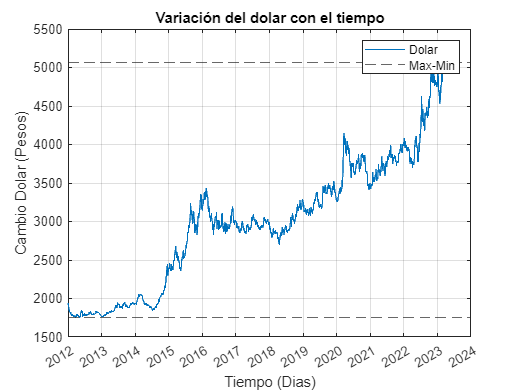

[data,header] = xlsread('DB Datos.xlsx',1);
fecha = datetime(header(2:end,1),'InputFormat','dd/MM/yyyy');
%hold on;
plot(fecha,database);
datetick('x','yyyy');
xlabel('Tiempo (Dias)');
ylabel('Cambio Dolar (Pesos)');
yline(1754.89,'--');
yline(5061.21,'--');
title('Variación del dolar con el tiempo');
legend('Dolar','Max-Min');
grid on;

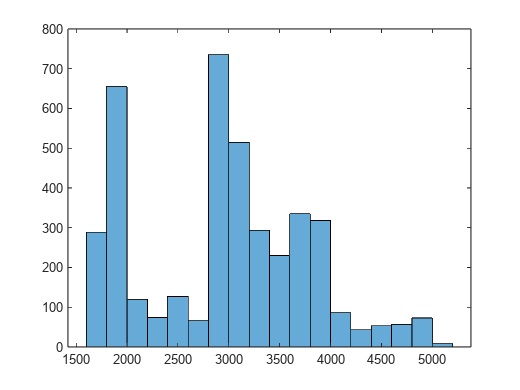

%hold off;
figure;
histogram(dolar);

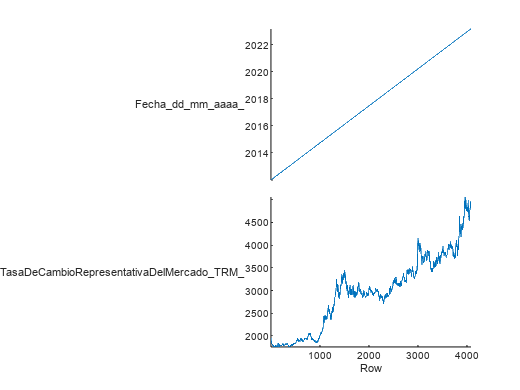

figure;
stackedplot(dolarhisto);

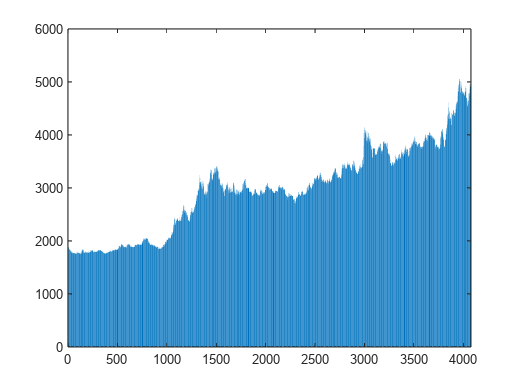

figure;
bar(data);

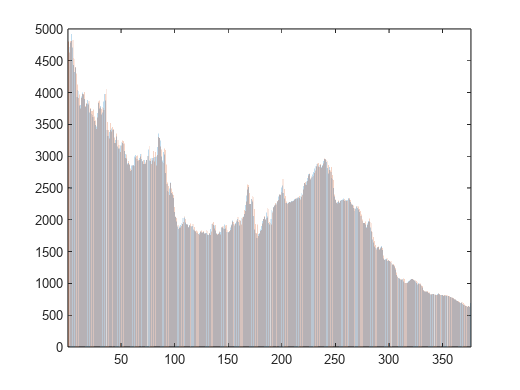

figure;
bar(nums,'DisplayName','nums');

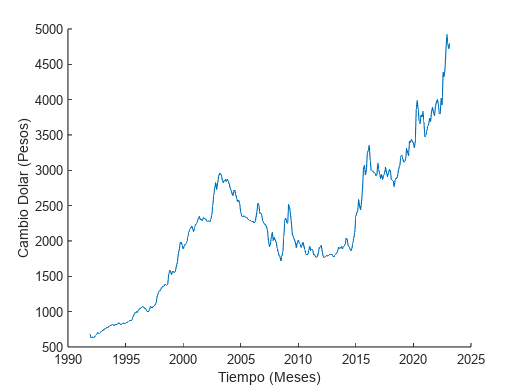

figure;
hold on;
mes = xlsread('DB Datos.xlsx',Meses,'A2:A377');
X = datetime(raw(2:end,1),'InputFormat','dd/MM/yyyy');
y = xlsread('DB Datos.xlsx',Meses,'B2:B377');
plot(X,y);
datetick('x','yyyy');
xlabel('Tiempo (Meses)');
ylabel('Cambio Dolar (Pesos)');
hold off

%----------------------------------------------------------------
load DolarDB.mat;
save DolarDB;